clear all;
clc;
close all;

xn = [3, 1, 4, 2];

x=xn;
p = nextpow2(length(x));
x = [x zeros(1, (2^p) - length(x))];
N = length(x);
S = log2(N);
Half = 1;
x = bitrevorder(x);
for stage = 1:S
    for index = 0:(2^stage):(N - 1)
        for n = 0:(Half - 1)
            pos = n + index + 1;
            pow = (2^(S - stage)) * n;
            w = exp((-1i) * (2 * pi) * pow / N);
            a = x(pos) + x(pos + Half) .* w;
            b = x(pos) - x(pos + Half) .* w;
            x(pos) = a;
            x(pos + Half) = b;
        end
    end
    Half = 2 * Half;
end
y=x;
disp("Radix-2 DIT FFT method result")

Radix-2 DIT FFT method result


y

y =   10.0000 + 0.0000i  -1.0000 + 1.0000i   4.0000 + 0.0000i  -1.0000 - 1.0000i



Xvk = fft(xn, N);
disp("Direct computation")

Direct computation


Xvk

Xvk =   10.0000 + 0.0000i  -1.0000 + 1.0000i   4.0000 + 0.0000i  -1.0000 - 1.0000i


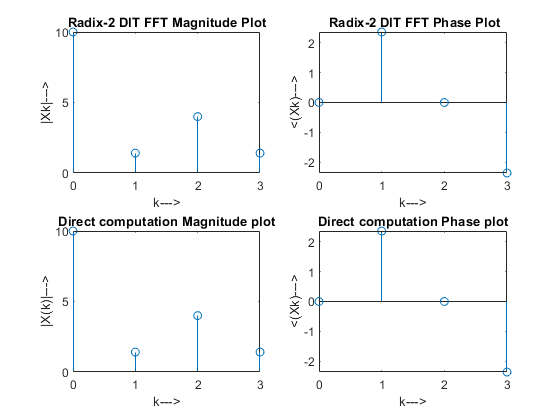


k = 0:N - 1;
subplot(2, 2, 1)
stem(k, abs(y))
xlabel('k--->')
ylabel('|Xk|--->')
title('Radix-2 DIT FFT Magnitude Plot')

subplot(2, 2, 2)
stem(k, angle(y))
xlabel('k--->')
ylabel('<(Xk)--->')
title(' Radix-2 DIT FFT Phase Plot')

subplot(2, 2, 3)
stem(k, abs(Xvk))
xlabel('k--->')
ylabel('|X(k)|--->')
title('Direct computation Magnitude plot')

subplot(2, 2, 4)
stem(k, angle(Xvk))
xlabel('k--->')
ylabel('<(Xk)--->')
title('Direct computation Phase plot')